# Three-Phase High-Power Converter Design and Analysis Workflow

## Overview

이 예는 고전력 컨버터 설계와 관련된 주요 단계를 보여줍니다. 고전력 컨버터는 미래의 전기 모빌리티 및 마이크로그리드 솔루션을 위한 중요한 구성 요소입니다. 비용 효과적이고 가볍고 효율적인 컨버터를 설계하려면 다양한 컨버터 설계 옵션과 배포 시나리오에 대한 자세한 분석을 수행해야 합니다. 이 예제는 절연 게이트 바이폴라 트랜지스터(IGBT) 디바이스를 사용하는 3상 2레벨 컨버터의 정상 상태, 과도 전기 및 열 특성을 시뮬레이션하는 데 도움이 됩니다.

Copyright 2021-2022 The MathWorks, Inc.

## Converter Design and Analysis Workflow

이 순서도는 컨버터 분석을 수행하는 방법과 설계 결정 및 구성 요소 매개변수의 효과를 연구하는 방법을 보여줍니다. 이 분석을 통해 효율적이고 비용 효율적인 설계를 찾을 수 있습니다.

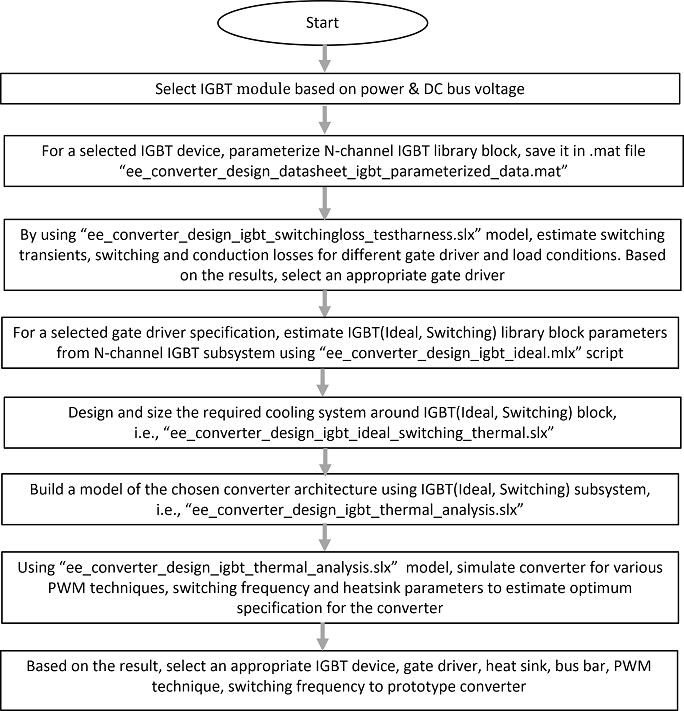

이 예제의 IGBT 및 다이오드 블록은 온 상태 손실과 스위칭 손실을 올바르게 캡처하도록 파라미터화되어 있습니다. N-채널 IGBT 블록의 **모델링 옵션 파라미터**는 다음과 같이 설정됩니다. `Full I-V and capacitance characteristics`. The **Diode model** parameter of the Diode block is set to `Tabulated I-V curve`. 제조업체 데이터시트의 특성 곡선은 이러한 블록에 대한 매개 변수를 제공합니다.

이 예제를 다른 IGBT 및 다이오드 디바이스에 사용하려면 트레이드오프 연구 및 설계 최적화를 수행하기 위해 시뮬레이션에 효율적인 적절한 파라미터화된 데이터를 제공해야 합니다.

`The ConverterDesignIGBTDatasheetParameters` MAT 파일에는 N채널 IGBT, 다이오드, 히트싱크 및 IGBT(이상, 스위칭) 블록에 대한 파라미터화된 데이터가 포함되어 있습니다. 워크스페이스에서 디바이스 파라미터를 로드하려면 MATLAB 명령 창에서 다음을 입력합니다:

load("ConverterDesignIGBTDatasheetParameters.mat");

다음 사용 중 오류가 발생함: load
파일 또는 디렉터리 'ConverterDesignIGBTDatasheetParameters.mat'을(를) 찾을 수 없습니다.

## **High-Power Converter Design Data Flow Diagram**

This figure shows the date flow and the respective file names used in this example.

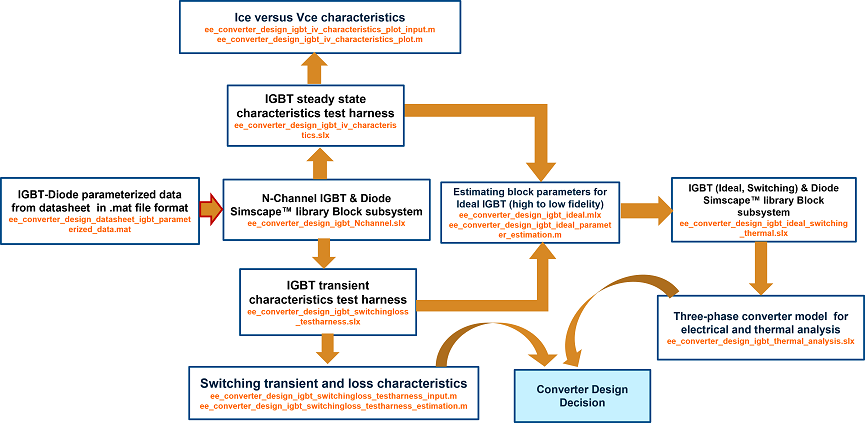

## **Select the IGBT Device**

This example is based on a 15 kW converter that operates in a three-phase grid with frequency of 60Hz and line voltage of 208 V. The RMS current of the converter is equal to 15e3/(sqrt(3)*208) = 41.6 Amperes and the current peak is equal to 59 Amperes. Because the minimum required DC bus voltage is equal to 2*208*sqrt(2/3) = 340 Volts, this example chooses standard 400V DC bus.

Due to the required currents and voltage, the converter needs an IGBT rated at more than 450Vdc and 50A. The TO-247 package contains an IGBT device with a continuous current rating of 50 Amperes and 650 Volts rating. The parasitic inductance of the busbar that connects the IGBT device with the DC bus is assumed to be 30nH. The busbar inductance is calculated either through lab measurement or by 3-D electromagnetic simulation.

## **Open the N-Channel IGBT Model Subsystem**

input data for the N-Channel IGBT block is derived from the manufacturer datasheet.

For more information about the N-Channel IGBT, Diode, and the other converter parameters and their respective units, see [`ConverterDesignIGBTInputData`](matlab:open('ConverterDesignIGBTInputData')) MLX file.

A Subsystem Reference model contains the parameterized N-Channel IGBT block. Use this subsystem to define the block once and then use it in multiple models. The Subsystem Reference includes the terminal lead parasitic inductance.

 
% Parameterized datasheet data for N-channel and ideal, switching IGBT blocks
load('ConverterDesignIGBTDatasheetParameters'); % loading device parameter
open_system('ConverterDesignNChannelIGBT');

## Design the Gate Driver

Simscape Electrical enables you to design a gate driver circuit for controlling power electronics devices. 

This example models three different gate driver designs.

For more information about the gate driver circuits, see [`ConverterDesignIGBTGateDriver`](matlab:open('ConverterDesignIGBTGateDriver')) MLX file.

## IGBT Steady State Characteristics 

 The `TestHarnessNChannelIGBT` SLX model provides a test harness to plot the steady state $I_{\textrm{ce}\;} \;\textrm{versus}\;V_{\textrm{ce}\;}$curve for different junction temperature $\left(T_{\left.J\;\right)} \right)$ and gate-emitter voltage $\left(V_{\textrm{ge}} \right)$.

To define simulation parameters, in the `TestHarnessNChannelIGBT` SLX model open the "Specify Test Parameters" mask in the top right corner. Then click on "Plot iv-characteristics" button to get the required i-v characteristics curve.

 
open_system('TestHarnessNChannelIGBT');

시스템 또는 파일 'TestHarnessNChannelIGBT'을(를) 찾을 수 없습니다. 'TestHarnessNChannelIGBT'은(는) 
  Three-Phase High-Power Converter Design and Analysis Workflow
  Test Harness to Generate IV Characteristics of N-Channel IGBT에 사용되었습니다.

## Estimate the Switching Losses

The `ConverterDesignIGBTSwitchingImageloss_testharness` SLX model, provides test harness that plots the switching loss characteristics for various IGBT simulation parameters:

- Collector-emitter current$\;\left(I_{\textrm{ce}\;} \right)$

- PWM switching frequency $\left(f_{\textrm{pwm}} \right)$

- Gate-emitter voltage $\left(V_{\textrm{ge}\;} \right)$

- Collector-emitter voltage $\left(V_{\textrm{ce}\;} \right)$ 

- Gate resistance $\left(R_{\textrm{gon}\;} \;\textrm{and}\;R_{g\;\textrm{off}} \right)$

- Junction temperature $\left(T_{J\;} \right)$

This model plots the IGBT characteristics for both double pulse and sinusoidal PWM gate signals. The IGBT device under test is placed in the lower (IGBTL) leg of a converter. A double pulse gate signal is used to determine the single turn-on and turn-off characteristics. A sinusoidal PWM gate modulation signal is used along with a sinusoidal output collector current to simulate the voltage$\left(V_{\textrm{ce}} \right)$ and current $\left(I_{\textrm{ce}} \right)$ stress on the IGBT-diode device combination in a typical two-level converter. A sinusoidal output load current$\;\left(I_{\textrm{ce}} \right)$ with sinusoidal voltage modulation signal  enables you to simulate for different power factor, power frequency, and switching frequency.

In the two-level converter, when bottom IGBT device is turned-on, the conduction transfer from top diode to bottom IGBT and vice versa during IGBT-turn-off. Busbar inductance influence the turn-off switching loss, it creates off state voltage spike across the device. Diode reserve recovery current affects the IGBT turn-on characteristics. It creates on-state current spike through the device.

To define the simulation parameters and to plot the switching loss characteristics, open the `ConverterDesignIGBTSwitchingImageloss_testharness` SLX model and click the "Specify Test Condition" mask in the top right corner. To get the required switching characteristics curve, click on the "Plot the characteristics" button.

 
open_system('ConverterDesignIGBTSwitchingImageloss_testharness');

## Estimate the IGBT (Ideal, Switching) Block Parameters 

IGBT (Ideal, Switching) blocks are better suited for simulating large model for harmonics and thermal analysis.

To estimate the parameters of the IGBT(Ideal, Switching) library block from N-Channel IGBT blocks, see [`ConverterDesignIdealIGBT`](matlab:open('ConverterDesignIdealIGBT')) MLX file.

## Open the Ideal IGBT Subsystem with Thermal Network

A Subsystem Reference model contains the parameterized IGBT(Ideal, Switching) block with heatsink. Use this subsystem to define the device once and use it multiple models.

 
% Loading parameterized datasheet data for IGBT(ideal, switching) block, diode and heat sink
load('ConverterDesignIGBTDatasheetParameters');
% Opening ideal IGBT subsystem reference model with simple external cooling thermal circuit
open_system('ConverterDesignIdealSwitchingThermalIGBT');

## Evaluate Temperature Rise in Three-Phase High Power Converter with Cooling System

To study the temperature rise, use the `ConverterDesign` SLX model. This model helps you choosing the design parameters such as the required cooling system, the PWM technique, and the switching frequency. It also helps you selecting the various simulation parameters by clicking on the "Select parameters" mask on the top right corner of the model. To simulate the system for the given test condition, click on the "Load parameters and simulate" button. 

 
open_system('ConverterDesign');

To close all the worksflow model files.

 
bdclose('ConverterDesignNChannelIGBT');
bdclose('ConverterDesignIdealSwitchingThermalIGBT');
bdclose('ConverterDesignIdealGateDrive');
bdclose('ConverterDesignOptocouplerGateDrive');
bdclose('ConverterDesignElectromagneticGateDrive');
bdclose('TestHarnessNChannelIGBT');
bdclose('ConverterDesignIGBTSwitchingImageloss_testharness');
bdclose('ConverterDesign');
edit 'ConverterDesignIGBTWorkflow.mlx'